# DSZOB, cvičenie 4.

## **Zadanie:**

## **Úloha 1 - **Analýza signálu

**Nasnímajte signál zvuku ladičky. **

Vizualizujte nasnímaný signál v priestorovej doméne. Na základe vizualizácie vyberte vhodný úsek, vypočítajte a vizualizujte preň Fourierovu transformáciu:

- Cez funkciu **fft** na malej vzorke dát (napr. 512)

- Prepočítajte index spektrálneho koeficienta na frekvenciu pre najväčsiu hodnotu v grafe

- Cez funkciu **spectrogram**

- Zistite dominantnú frekvenciu daného signálu a vyznačte ju v grafe.

**Postup vhodne dokumentuje (Code/Text bloky)!**

## **Riešenie:**

%1.1. Vizualizujte nasnímaný signál v priestorovej doméne.  Je ok ak FS = 4410 a nie 44100?
ladicka = importdata("ladicka.wav")

ladicka = struct with fields:
    data: [346112×2 double]
      fs: 44100


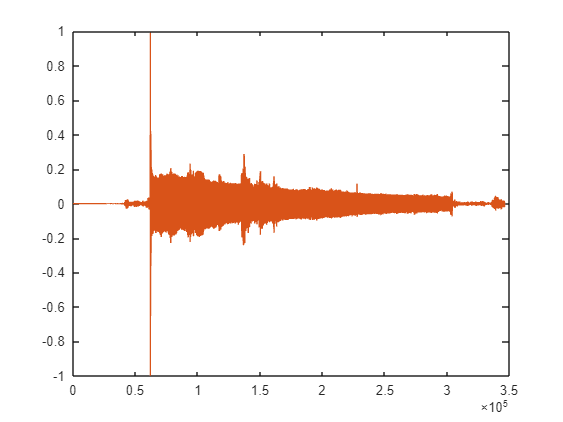

fado = importdata("Fado1.wav");
fs = ladicka.fs;
rawSignal = ladicka.data;
plot(rawSignal)

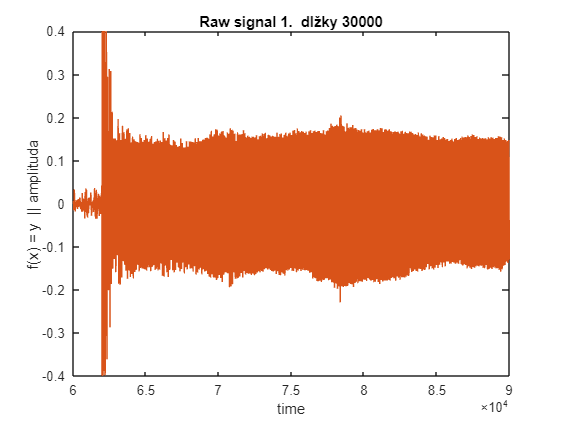

%1.2 Na základe vizualizácie vyberte vhodný úsek, vypočítajte a vizualizujte preň Fourierovu transformáciu:
plot(rawSignal)
xlim([60000 90000])
ylim([-0.4 0.4])
title("Raw signal 1.  dlžky 30000")
xlabel("time")
ylabel("f(x) = y  || amplituda")

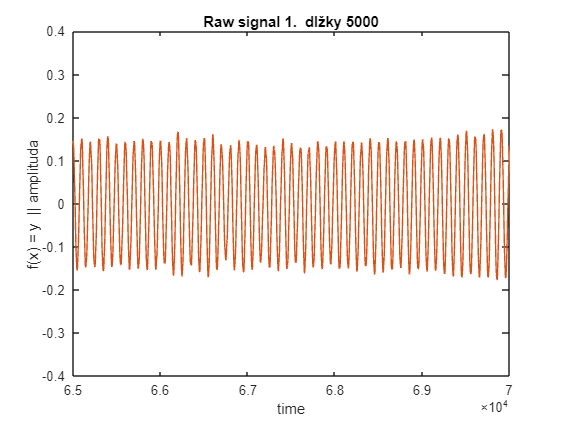

plot(rawSignal)
xlim([65000 70000])
ylim([-0.4 0.4])
title("Raw signal 1.  dlžky 5000")
xlabel("time")
ylabel("f(x) = y  || amplituda")

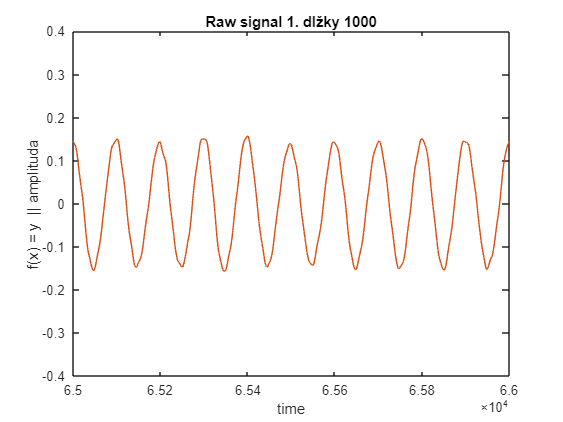


plot(rawSignal)
xlim([65000 66000])
ylim([-0.4 0.4])
title("Raw signal 1. dlžky 1000")
xlabel("time")
ylabel("f(x) = y  || amplituda")

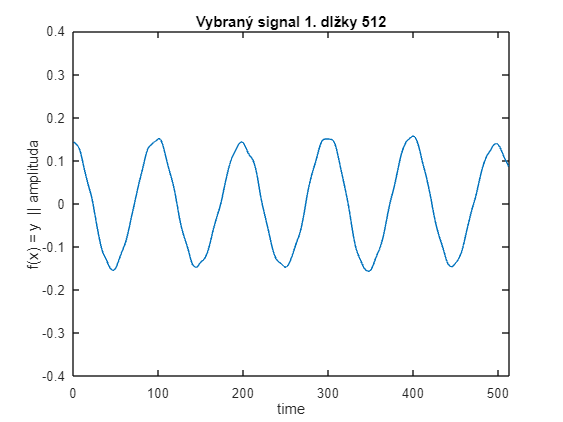

    % 1.2.1 Cez funkciu fft na malej vzorke dát (napr. 512)
     choosenSignal = rawSignal(65001:65512);
     plot(choosenSignal)
     xlim([0 513])
     ylim([-0.4 0.4])
     title("Vybraný signal 1. dlžky 512")
     xlabel("time")
     ylabel("f(x) = y  || amplituda")

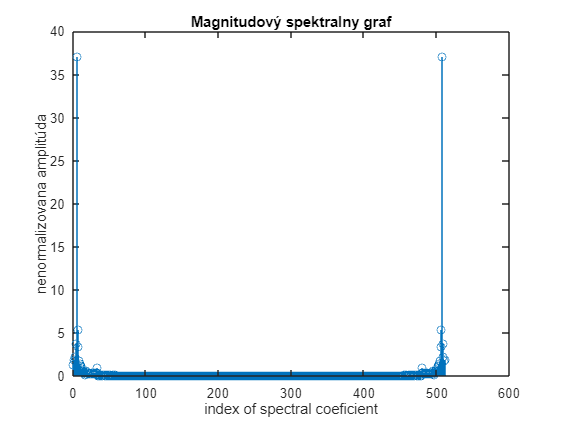


     imDFT1 = fft(choosenSignal);
     dft1 = abs(imDFT1);
     stem(dft1)
     title("Magnitudový spektralny graf")
     xlabel("index of spectral coeficient")
     ylabel("nenormalizovana amplitúda")

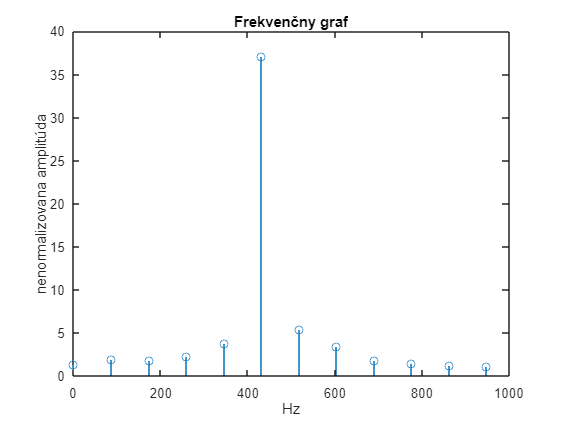

    %Prepočítajte index spektrálneho koeficienta na frekvenciu pre najväčsiu hodnotu v grafe
     xStem = -fs/2 + 1:fs/512:fs/2;
     stem(xStem, fftshift(dft1))
     title("Frekvenčny graf")
     xlabel("Hz")
     ylabel("nenormalizovana amplitúda")
     xlim([-1 1000])

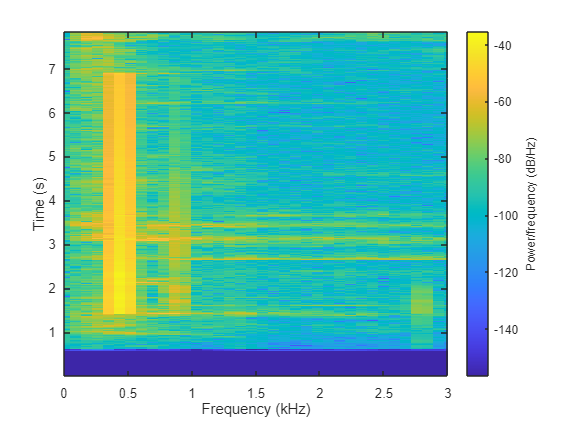

    %Cez funkciu spectrogram zobraz frekvenčné spektrum, celého raw signálu (a uprataj magnitudove spektrum s hammingtonovym oknom)
     spectrogram(rawSignal(:,1), hamming(512), 256, 512,fs)%celý signal, okienko pre elimináciu of spectral leakage, velkosti overlapu medzi jednotlivými okienkami (dlžkami na vzorkovanie), dlžka vzorky do fft funkcie, rozsah frequency sampling
     xlim([0 3]) %vysledok je graf 3-rozmerov, 1. frekvenčný rozsah, 2. časom trvania nahravky, 3. silou danej frekvencie v danom čase

    %Zistite dominantnú frekvenciu daného signálu a vyznačte ju v grafe.
    [Max, indexOfMax] = max(dft1)

Max = 37.1393

indexOfMax = 6

    foundFreq = (indexOfMax-1)/(512/2) * (fs/2);
    display(foundFreq + "Hz")

    "430.6641Hz"



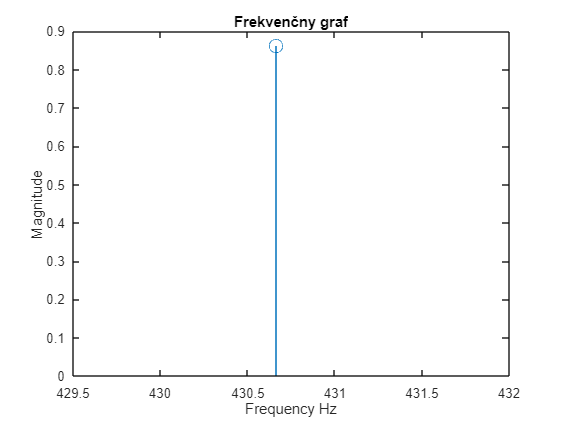


    stem(foundFreq, Max*(1024/fs), 'o','MarkerSize',10)
     title("Frekvenčny graf")
     xlabel("Frequency Hz")
     ylabel("Magnitude")

    % xlim([-1 1000])

## **Úloha 2 - Zero Padding v spektrálnej doméne**

Vygenerujte si náhodne zložený signál s dĺžkou 1 sekunda a s voľne zvolenou malou vzorkovacou frekvenciou. Zvolte si parametre signálu tak, aby najväčšia frekvencia generovaného signálu neprekročila 16Hz a vzorkovacia frekvencia pod 64Hz. Dbajte pri tom na to, aby bol splnený Nyquistov teorém. 

Vykonajte zero padding signálu v spektrálnej doméne tak, že doplníte nulami spektrum od jeho stredu (stred symetrie musí ostať zachovaný). Doplnenie vykonajte na velkosť vzorky 1024. Následne vykonajte spätnú transformáciu do časovej domény. Pôvodný signál, ako aj novo vytvorený spoločne vizualizujte v jednom grafe, kde x-os bude reprezentovať čas v rozsahu 1 sek.

Zodpovedajte nasledovné otázky:

- Akú výhodu nam priniesol zero padding v spektre?

- Vie nám zero padding v spektre pomôcť v prípade, ak bol porušený Nyquistov teorém v pôvodnom signále? (áno/nie)

## Pomôcky:

- complex()

- zeros()

- ifft()

## Poznámka:

- Spektrum signálu obsahuje magnitúdovú aj fázovú zložku. Pri dopĺňaní spektra nulami teda pracujeme s komplexnými číslami (0 + 0*i)

- Po spätnom prepočte inverznej transformacie prenásobte výsledný signál konštantou 1024/Fs pre normalizáciu hodnôt na veľkosť okienka

## **Riešenie:**

% 1.1 Vygenerujte si náhodne zložený signál s dĺžkou 1 sekunda a s voľne
% zvolenou malou vzorkovacou frekvenciou Zvolte si parametre signálu tak,
% aby najväčšia frekvencia generovaného signálu neprekročila 16Hz a
% vzorkovacia frekvencia pod 64Hz. Dbajte pri tom na to, aby bol splnený
% Nyquistov teorém. (stačí keď freq*2 > FS)
% čize fq < 16, fs = 64
fq2=15;
fs2=64

fs2 = 64

x_0 = 0:1/fs2:1

x_0 =          0    0.0156    0.0312    0.0469    0.0625    0.0781    0.0938    0.1094    0.1250    0.1406    0.1562    0.1719    0.1875    0.2031    0.2188    0.2344    0.2500    0.2656    0.2812    0.2969    0.3125    0.3281    0.3438    0.3594    0.3750    0.3906    0.4062    0.4219    0.4375    0.4531    0.4688    0.4844    0.5000    0.5156    0.5312    0.5469    0.5625    0.5781    0.5938    0.6094    0.6250    0.6406    0.6562    0.6719    0.6875    0.7031    0.7188    0.7344    0.7500    0.7656


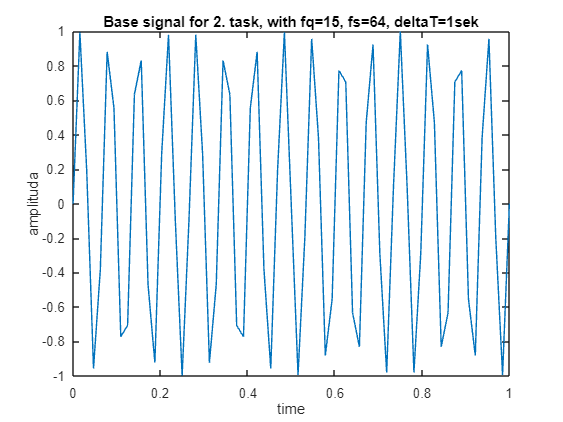

signal = sin(2*pi*15*x_0);
plot(x_0, signal)
     title("Base signal for 2. task, with fq=15, fs=64, deltaT=1sek")
     xlabel("time")
     ylabel("amplituda")


% Vykonajte zero padding signálu v spektrálnej doméne tak,
% že doplníte nulami spektrum od jeho stredu (stred symetrie musí ostať zachovaný).
% Doplnenie vykonajte na velkosť vzorky 1024. Následne vykonajte spätnú transformáciu do časovej domény. 
imDFT2 = fft(signal)

imDFT2 =   -0.0000 + 0.0000i   0.0026 - 0.0535i   0.0105 - 0.1082i   0.0242 - 0.1654i   0.0444 - 0.2266i   0.0724 - 0.2937i   0.1102 - 0.3693i   0.1608 - 0.4571i   0.2291 - 0.5628i   0.3232 - 0.6955i   0.4572 - 0.8712i   0.6593 - 1.1209i   0.9918 - 1.5138i   1.6295 - 2.2428i   3.3135 - 4.1257i  19.4326 -21.9349i  -6.5748 + 6.7356i  -3.1307 + 2.9116i  -2.1825 + 1.8414i  -1.7418 + 1.3310i  -1.4892 + 1.0279i  -1.3269 + 0.8242i  -1.2149 + 0.6756i  -1.1341 + 0.5607i  -1.0737 + 0.4677i  -1.0278 + 0.3898i  -0.9924 + 0.3225i  -0.9651 + 0.2628i  -0.9442 + 0.2087i  -0.9286 + 0.1586i  -0.9175 + 0.1114i  -0.9103 + 0.0661i  -0.9068 + 0.0219i  -0.9068 - 0.0219i  -0.9103 - 0.0661i  -0.9175 - 0.1114i  -0.9286 - 0.1586i  -0.9442 - 0.2087i  -0.9651 - 0.2628i  -0.9924 - 0.3225i  -1.0278 - 0.3898i  -1.0737 - 0.4677i  -1.1341 - 0.5607i  -1.2149 - 0.6756i  -1.3269 - 0.8242i  -1.4892 - 1.0279i  -1.7418 - 1.3310i  -2.1825 - 1.8414i  -3.1307 - 2.9116i  -6.5748 - 6.7356i


dft2 = abs(imDFT2)

dft2 =     0.0000    0.0536    0.1087    0.1672    0.2309    0.3025    0.3854    0.4846    0.6077    0.7669    0.9839    1.3004    1.8098    2.7723    5.2915   29.3048    9.4125    4.2754    2.8555    2.1921    1.8095    1.5620    1.3902    1.2651    1.1712    1.0992    1.0435    1.0003    0.9670    0.9420    0.9242    0.9127    0.9070    0.9070    0.9127    0.9242    0.9420    0.9670    1.0003    1.0435    1.0992    1.1712    1.2651    1.3902    1.5620    1.8095    2.1921    2.8555    4.2754    9.4125


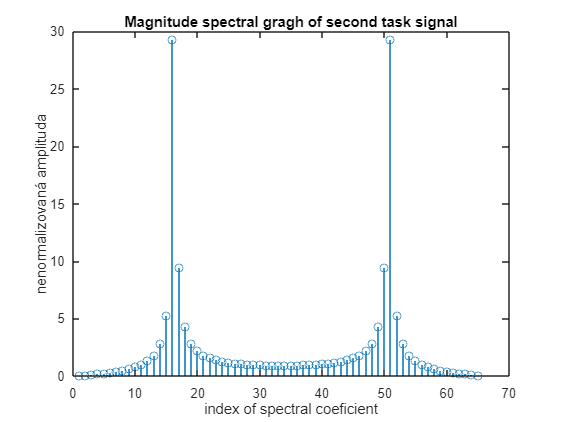

stem(dft2)
     title("Magnitude spectral gragh of second task signal")
     xlabel("index of spectral coeficient")
     ylabel("nenormalizovaná amplituda")


     [Max2, indexOfMax2] = max(dft2)

Max2 = 29.3048

indexOfMax2 = 16

     foundFreq = (indexOfMax -1) / (512/2) * (fs2/2) 

foundFreq = 0.6250

xStem2 = -fs2/2:fs2/2

xStem2 =    -32   -31   -30   -29   -28   -27   -26   -25   -24   -23   -22   -21   -20   -19   -18   -17   -16   -15   -14   -13   -12   -11   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17


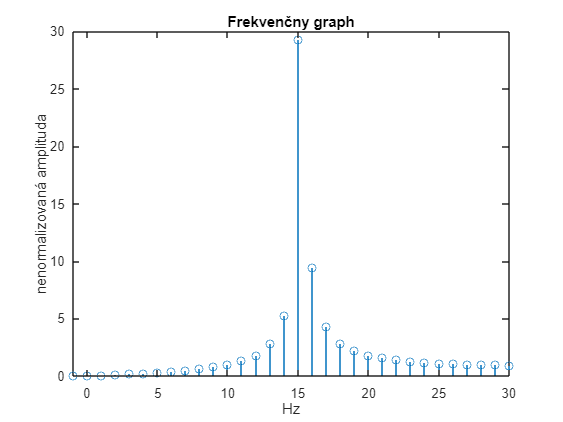

stem(xStem2, fftshift(dft2))
     title("Frekvenčny graph")
     xlabel("Hz")
     ylabel("nenormalizovaná amplituda")
     xlim([-1 30])

  %Doplnenie núl/zero padding
  zeroPaddign = zeros(1,1024-length(imDFT2));  %vytvorenie retazca potrebne dlzky pre doplnenie do aktualneho signalu
  complexZeroPadding = complex(zeroPaddign);   %naplnenie spomenuteho retazca nulovými compexnými hodnotami
  newImDFT2 = [imDFT2(1:33), complexZeroPadding, imDFT2(34:65)]  %finally zero-padding

newImDFT2 =   -0.0000 + 0.0000i   0.0026 - 0.0535i   0.0105 - 0.1082i   0.0242 - 0.1654i   0.0444 - 0.2266i   0.0724 - 0.2937i   0.1102 - 0.3693i   0.1608 - 0.4571i   0.2291 - 0.5628i   0.3232 - 0.6955i   0.4572 - 0.8712i   0.6593 - 1.1209i   0.9918 - 1.5138i   1.6295 - 2.2428i   3.3135 - 4.1257i  19.4326 -21.9349i  -6.5748 + 6.7356i  -3.1307 + 2.9116i  -2.1825 + 1.8414i  -1.7418 + 1.3310i  -1.4892 + 1.0279i  -1.3269 + 0.8242i  -1.2149 + 0.6756i  -1.1341 + 0.5607i  -1.0737 + 0.4677i  -1.0278 + 0.3898i  -0.9924 + 0.3225i  -0.9651 + 0.2628i  -0.9442 + 0.2087i  -0.9286 + 0.1586i  -0.9175 + 0.1114i  -0.9103 + 0.0661i  -0.9068 + 0.0219i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


  stem(abs(newImDFT2))
     title("Magnitudový spektralny graf po zero-padding")
     xlabel("index of spectral coeficient")
     ylabel("nenormalizovana amplitúda")
% Pôvodný signál, ako aj novo vytvorený spoločne vizualizujte v jednom grafe,
% kde x-os bude reprezentovať čas v rozsahu 1 sek.
reSignal = ifft(newImDFT2)

reSignal =          0    0.0020    0.0045    0.0075    0.0111    0.0151    0.0195    0.0242    0.0292    0.0342    0.0393    0.0443    0.0491    0.0535    0.0575    0.0610    0.0638    0.0659    0.0673    0.0678    0.0675    0.0663    0.0643    0.0614    0.0578    0.0534    0.0483    0.0427    0.0365    0.0300    0.0231    0.0160    0.0088    0.0017   -0.0054   -0.0123   -0.0189   -0.0252   -0.0311   -0.0365   -0.0414   -0.0458   -0.0496   -0.0529   -0.0556   -0.0578   -0.0594   -0.0605   -0.0611   -0.0613


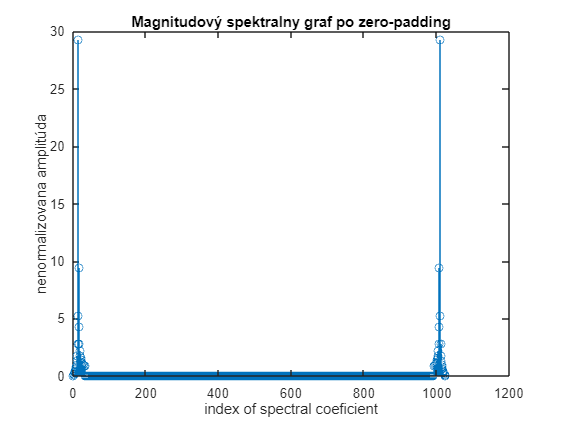

    %Akú výhodu nam priniesol zero padding v spektre?
hold off

plot(reSignal*(1024/fs2))%(1024/fs2) normalizácia amplitud po ich 
hold on
x_1 = 0:1024/64:1024

x_1 =      0    16    32    48    64    80    96   112   128   144   160   176   192   208   224   240   256   272   288   304   320   336   352   368   384   400   416   432   448   464   480   496   512   528   544   560   576   592   608   624   640   656   672   688   704   720   736   752   768   784


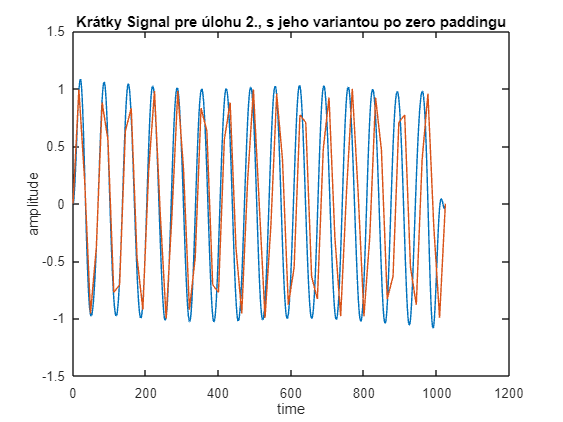

plot(x_1,signal)
hold off
title("Krátky Signal pre úlohu 2., s jeho variantou po zero paddingu")
     xlabel("time")
     ylabel("amplitude")

%K predposlednej otázke, aký vlyv mal zero padding na spektralny graf.
    %Zlepsil rozlíšenie výsledneho signalu, po inverznej fourierovej transf.

    
%Vie nám zero padding v spektre pomôcť v prípade, ak bol porušený Nyquistov teorém v pôvodnom signále? (áno/nie)
fs3 = 24

fs3 = 24

x_2 = 0:1/fs3:1

x_2 =          0    0.0417    0.0833    0.1250    0.1667    0.2083    0.2500    0.2917    0.3333    0.3750    0.4167    0.4583    0.5000    0.5417    0.5833    0.6250    0.6667    0.7083    0.7500    0.7917    0.8333    0.8750    0.9167    0.9583    1.0000


signal2 = sin(2*pi*fq2*x_2);
imDFT3 = fft(signal2)

imDFT3 =   -0.0000 + 0.0000i  -0.0066 + 0.0525i  -0.0276 + 0.1076i  -0.0667 + 0.1685i  -0.1320 + 0.2402i  -0.2404 + 0.3309i  -0.4304 + 0.4583i  -0.8077 + 0.6682i  -1.7918 + 1.1371i  -8.3079 + 3.9094i   6.2760 - 2.0392i   3.0641 - 0.5845i   2.4712 - 0.1555i   2.4712 + 0.1555i   3.0641 + 0.5845i   6.2760 + 2.0392i  -8.3079 - 3.9094i  -1.7918 - 1.1371i  -0.8077 - 0.6682i  -0.4304 - 0.4583i  -0.2404 - 0.3309i  -0.1320 - 0.2402i  -0.0667 - 0.1685i  -0.0276 - 0.1076i  -0.0066 - 0.0525i


zeroPaddign1 = zeros(1,1024-length(imDFT3));
complexZeroPadding1 = complex(zeroPaddign1);
newImDFT3 = [imDFT3(1:13), complexZeroPadding1, imDFT3(14:25)]

newImDFT3 =   -0.0000 + 0.0000i  -0.0066 + 0.0525i  -0.0276 + 0.1076i  -0.0667 + 0.1685i  -0.1320 + 0.2402i  -0.2404 + 0.3309i  -0.4304 + 0.4583i  -0.8077 + 0.6682i  -1.7918 + 1.1371i  -8.3079 + 3.9094i   6.2760 - 2.0392i   3.0641 - 0.5845i   2.4712 - 0.1555i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


stem(abs(newImDFT3))
reSignal2 = ifft(newImDFT3)

reSignal2 =     0.0000   -0.0003   -0.0007   -0.0011   -0.0016   -0.0020   -0.0025   -0.0031   -0.0036   -0.0042   -0.0049   -0.0055   -0.0061   -0.0068   -0.0075   -0.0082   -0.0089   -0.0096   -0.0103   -0.0110   -0.0116   -0.0123   -0.0130   -0.0136   -0.0142   -0.0148   -0.0153   -0.0158   -0.0163   -0.0167   -0.0170   -0.0174   -0.0176   -0.0178   -0.0180   -0.0181   -0.0181   -0.0181   -0.0180   -0.0178   -0.0176   -0.0172   -0.0169   -0.0164   -0.0159   -0.0153   -0.0147   -0.0139   -0.0132   -0.0123


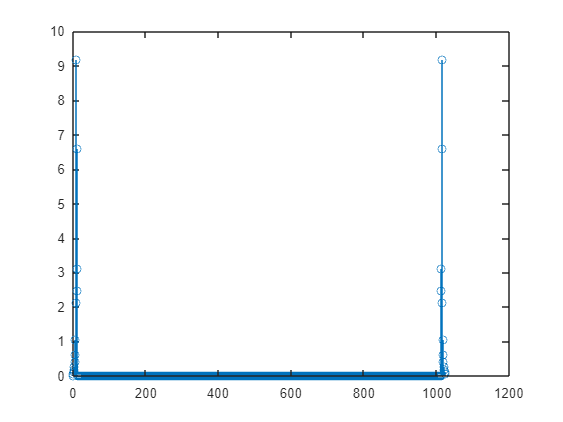

hold off

plot(reSignal2*(1024/fs3))%(1024/fs2) normalizácia amplitud po ich 
hold on
x_3 = 0:1024/24:1024

x_3 = 1.0e+03 *

         0    0.0427    0.0853    0.1280    0.1707    0.2133    0.2560    0.2987    0.3413    0.3840    0.4267    0.4693    0.5120    0.5547    0.5973    0.6400    0.6827    0.7253    0.7680    0.8107    0.8533    0.8960    0.9387    0.9813    1.0240


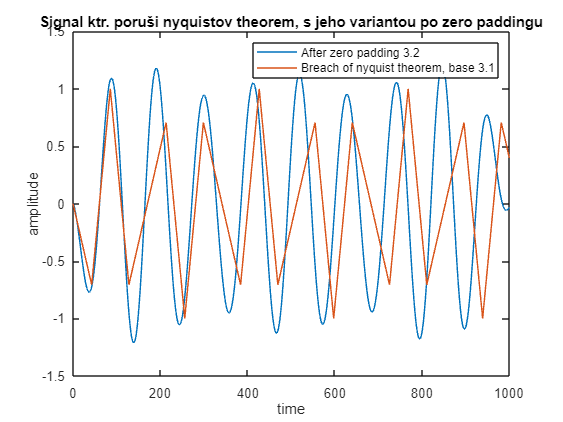

plot(x_3,signal2)
hold off
xlim([0 1000])
legend('After zero padding 3.2','Breach of nyquist theorem, base 3.1')
     title("Signal ktr. poruši nyquistov theorem, s jeho variantou po zero paddingu")
     xlabel("time")
     ylabel("amplitude")


%K poslednej otázke, vie nám zero padding pomôcť ak bol porušený nyquistov teorem pri vzorkovaní.
    %Nie, zero padding v konečnom výsledku "otučnuje" signál, nevie kompenzovať niečo čo tam chýba, alebo čo bolo skreslené porušením nyquistovho teoremu.